Question 6

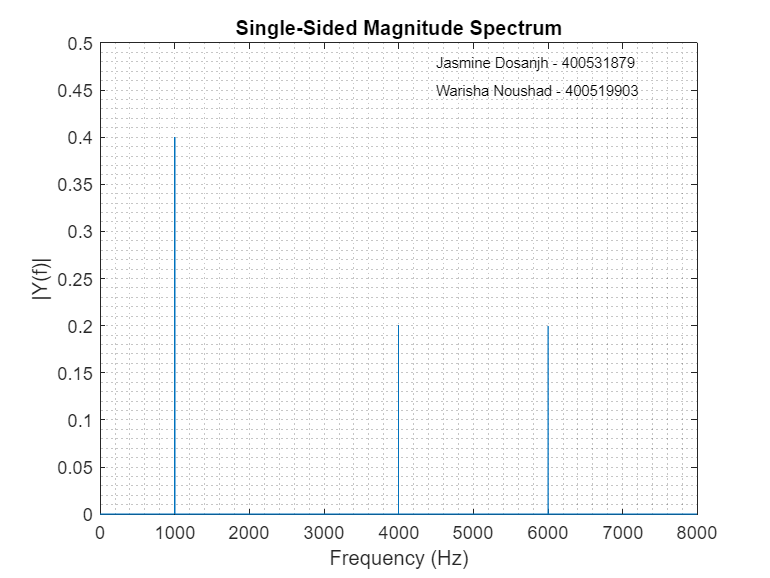

% Read in the signal from the audio file
[signal, Fs] = audioread("tones.wav"); 
L = length(signal);
T = 1/Fs;
t = [0:L-1]*T; 

% Take the DFT
Y = fft(signal)/L;
f = Fs/2*linspace(0,1,L/2+1);

% Plot the single-sided magnitude spectrum.
plot(f,2*abs(Y(1:L/2+1)));
title('Single-Sided Magnitude Spectrum')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
axis([0 Fs/2 0 .5]);
grid('minor');

%Export the graph
text(4500, 0.48, 'Jasmine Dosanjh - 400531879', 'FontSize', 8)
text(4500, 0.45, 'Warisha Noushad - 400519903', 'FontSize', 8)
exportgraphics(gcf, "P1_Q6.jpg")